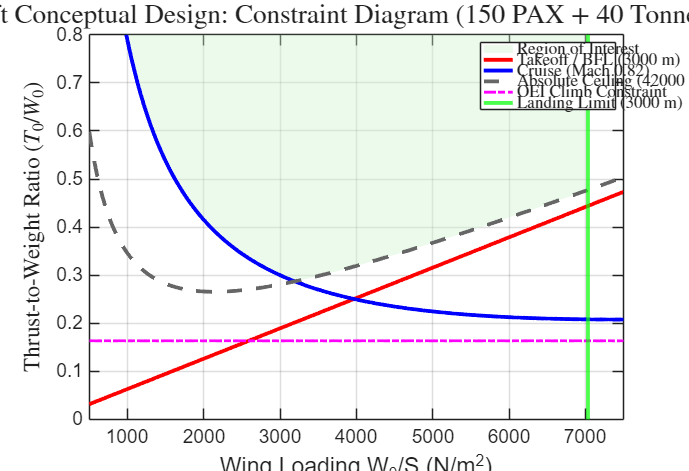

% AVD Constraint Diagram Code
% Ananjan Pillai
% Version 1: 11/10/2026
% This code should be able to create a constraint diagram plot for our
% aircraft using input values from Lea's Key_Param_recording.csv file
    % Important changeable variables have been indented

clear; clc; close all;

%% INPUT DEFINITIONS
% Importing the csv file
csvFilename = 'Key_Param_recording.csv';

opts = detectImportOptions(csvFilename); % Import Options
% be able to read from table using names 
paramTable = readtable(csvFilename, opts);
getParam = @(name) paramTable.Value(strcmp(paramTable.Parameter, name));

% Extracting values from csv file
AR = getParam('AR'); % Aspect Ratio
Swet_Sref = getParam('Swet_Sref'); % Wetted-to-reference area ratio
M_cruise = getParam('M_cruise'); % Cruise Mach No.
L_runway = getParam('L_runway'); % Min Runway Length
W0_guess = getParam('W_0_guess_init'); % MTOW Value (guess)
abs_ceil_ft = getParam('abs_ceiling_ft'); % Absolute ceiling [ft]
gamma_air = getParam('gamma_air'); % Specific Heats Ratio (Air)
R_air = getParam('R_air'); % R [J/(kg K)]
T_cruise_K = getParam('T_cruise_K'); % Cruise Temp (K)

% Manual Input Values
g = 9.81;
rho0 = 1.225; % Sea level air density
sigma_to = 1.0; % density ratio (rho/rho0) for sea level
CLmax_L = 2.40; % Landing CL_Max (slide 35, constraint diagram) ik
CLmax_TO = 1.80; % Take-off CL_Max ?
CL_LOF = 0.8 * CLmax_TO; % Lift-off CL_Max >?
e_oswald = 0.85; % Oswald span efficiency factor ik
CD0 = 0.020; % Zero-lift drag coefficient (slide 20, constraint diagram)ik
NE = 2; % No. of Engines
    alpha_to = 0.95; % Takeoff weight ratio
    alpha_cr = 0.90; % Cruise weight ratio 
    beta_cr = 0.25; % Thrust lapse ratio at cruise (slide 23, constraint diagram)
    alpha_ceil = 0.92; % Weight ratio at abs ceil
    beta_ceil = 0.20; % Thrust lapse ratio at abs ceil
K_R = 1.0; %Runway Correction Factor
Sa = 305; % Air Dist Safety Margin


%% EQUATIONS

WS = linspace(500, 7500, 500); % Range for Wing Loading in x axis [N/m^2]
ALD_max = 0.60 * L_runway; % Allowable Landing Distance (m)
WS_landing_limit = (ALD_max - Sa) * sigma_to * CLmax_L / (0.51 * K_R); % Wing Loading Limit for given ALD

% Raymer Takeoff Parameter
TOP_req = L_runway / (0.297 - 0.019 * NE);
TW_takeoff = (WS / (sigma_to * CL_LOF * TOP_req)) * (1 / alpha_to); % Plotting min. thrust-weight ratio from TOP
    h_cruise_m = 11000; % Cruise altitude approx. (m)

[~, ~, ~, rho_cruise] = atmosisa(h_cruise_m); % ISA value
q_cruise = 0.5 * rho_cruise * (M_cruise * sqrt(gamma_air * R_air * T_cruise_K))^2; % Dyn. Pressure
K_induced = 1 / (pi * AR * e_oswald); % Induced Drag Factor
TW_cruise = (alpha_cr / beta_cr) * ( (q_cruise * CD0 ./ WS) + (WS / q_cruise) * K_induced );

% Absolute Ceiling
h_ceil_m = abs_ceil_ft * 0.3048;
[~, ~, ~, rho_ceil] = atmosisa(h_ceil_m);
V_ceil = 150; % Est. Speed at Ceiling
q_ceil = 0.5 * rho_ceil * V_ceil^2;
TW_ceil = (alpha_ceil / beta_ceil) * ( (q_ceil * CD0 ./ WS) + (WS / q_ceil) * K_induced ); % Eqn. from slides

% OEI Climb Constraint
    gamma_req = 0.024; % Required climb gradient (2.4% for twin-engine)
TW_climb2 = (NE / (NE - 1)) * (gamma_req + 2 * sqrt(CD0 * K_induced)); 
TW_climb2_vec = TW_climb2 * ones(size(WS));

%% PLOTS (used AI for formatting)

figure('Name', 'Aircraft Constraint Diagram', 'Color', 'white', 'Position', [100, 100, 950, 650]);
hold on; grid on; box on;

plot(WS, TW_takeoff, 'r-', 'LineWidth', 2);
plot(WS, TW_cruise, 'b-', 'LineWidth', 2);
plot(WS, TW_ceil, 'Color', [0.4 0.4 0.4], 'LineWidth', 2, 'LineStyle', '--');
plot(WS, TW_climb2_vec, 'm-', 'LineWidth', 1.5, 'LineStyle', '-.');
xline(WS_landing_limit, 'g-', 'LineWidth', 2);

xlabel('Wing Loading W_0/S (N/m^2)', 'FontSize', 12);
ylabel('Thrust-to-Weight Ratio $(T_0/W_0)$', 'Interpreter', 'latex', 'FontSize', 12);
title('Aircraft Conceptual Design: Constraint Diagram ($150$ PAX + $40$ Tonnes Cargo)', 'Interpreter', 'latex', 'FontSize', 14);

legend('Takeoff / BFL ($3000$ m)', ...
       'Cruise (Mach $0.82$)', ...
       'Absolute Ceiling ($42000$ ft)', ...
       'OEI Climb Constraint', ...
       'Landing Limit ($3000$ m)', ...
       'Location', 'northeast', 'Interpreter', 'latex');

axis([500 7500 0 0.8]);

%% Highlighting Region of Interest
WS_feasible = WS(WS <= WS_landing_limit);
TW_upper = max([TW_takeoff(WS <= WS_landing_limit); TW_cruise(WS <= WS_landing_limit); TW_ceil(WS <= WS_landing_limit); TW_climb2_vec(WS <= WS_landing_limit)]);
fill_WS = [WS_feasible, fliplr(WS_feasible)];
fill_TW = [TW_upper, 0.8 * ones(size(WS_feasible))];
h_shade = fill(fill_WS, fill_TW, [0.8 0.95 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.4, 'DisplayName', 'Region of Interest');
uistack(h_shade, 'bottom');

S_ref_update = 9.81*W0_guess/3179

S_ref_update = 884.4121